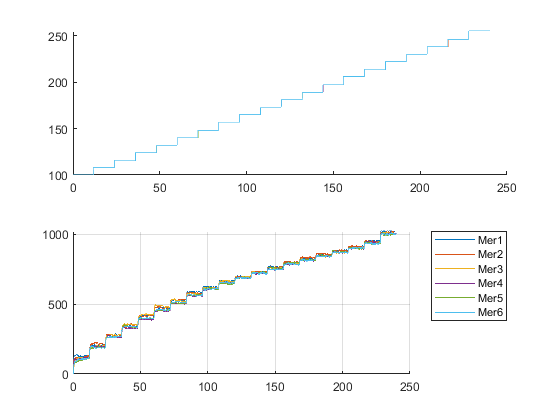

data = zeros(13541,3,6);
for i=1:12
    fileName = ['./dataRepo/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    data(:,:,i) = dt(2:13542,:);
end

figure;
for i=1:6
    subplot(2,1,1);    
    name = ['Mer',num2str(i)];
    hold on;
    plot(data(:,1,i),data(:,2,i), 'DisplayName',name);
    hold off;
    subplot(2,1,2);
    hold on;
    plot(data(:,1,i),data(:,3,i),'DisplayName',name)
    hold off;
end
legend('Location',"bestoutside");
grid on;

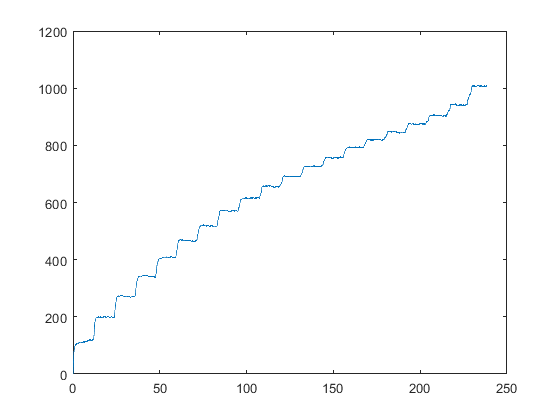

dataSimple = zeros(6,13541);
for i=1:6    
    dataSimple(i,:) = data(:,3,i)';
end
dataMean = mean(dataSimple);
dataMean = dataMean';
figure;
plot(data(:,1,1),dataMean(:),'DisplayName',name)

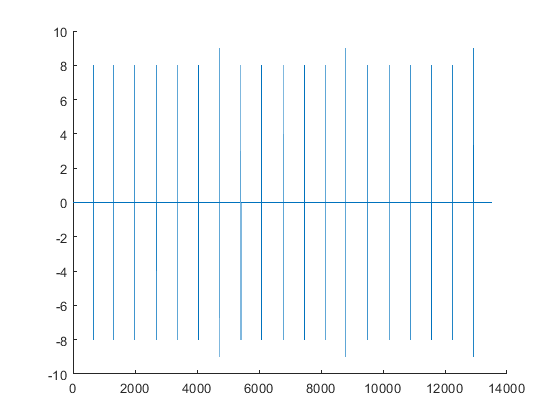

timeData = data(:,1,1);
inputData = data(:,2,1);
outputData = data(:,3,1);

diffVal = diff(inputData);
diffVal2 = diff(diffVal);
figure;
hold on;
%plot(diffVal)
plot(diffVal2)
hold off;

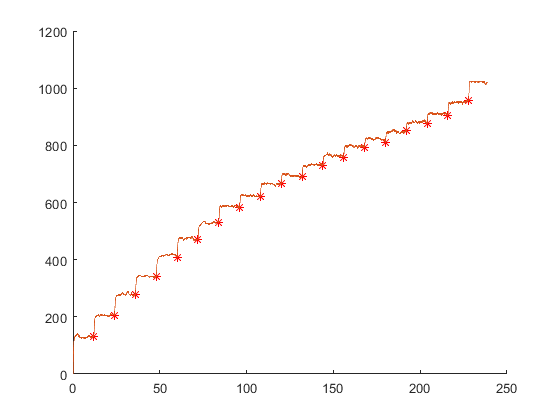


ids = find(or(diffVal > 4,diffVal < -4));
ln = size(ids,1);
finalData = zeros(ln,2);
for i=1:ln    
    finalData(i,1) = timeData(ids(i));
    finalData(i,2) = outputData(ids(i,1));
end

figure;
hold on;
plot(finalData(:,1),finalData(:,2),'*r');
plot(timeData,outputData);
hold off;